# Fourier Transforms and Properties

Dr. Matthew Nokleby, Wayne State University. ECE 4330, Winter 2018.

Let's get a sense of how the Fourier transform works by recording sounds and looking at the CTFT of the result. A few sounds we'll go for: an impulse function and a periodic signal.

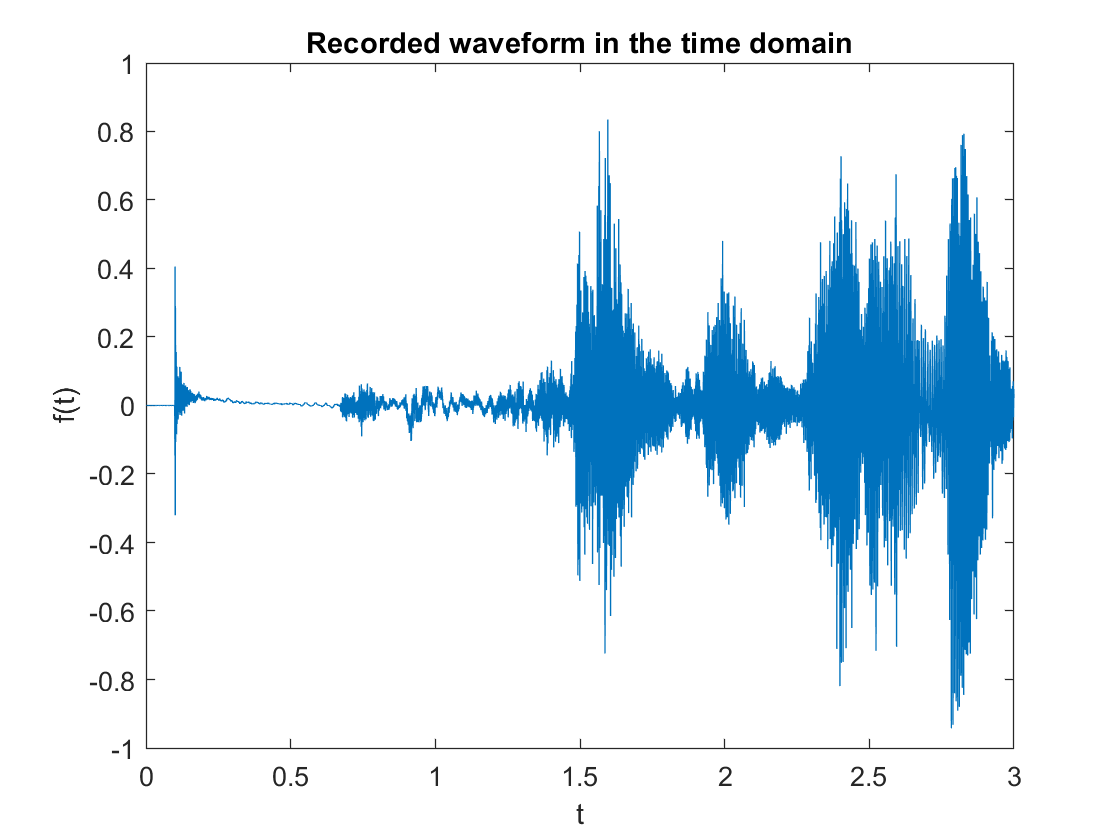

DURATION = 3; %how many seconds
FS = 44100; %Sampling frequency
tValues = linspace(0,DURATION,FS*DURATION);
recObj = audiorecorder(FS,16,1); 
recordblocking(recObj, DURATION);
f = getaudiodata(recObj);
close all;
plot(tValues,f);
title('Recorded waveform in the time domain');
xlabel('t');
ylabel('f(t)');

Now let's look at the Fourier transform of what we recorded.

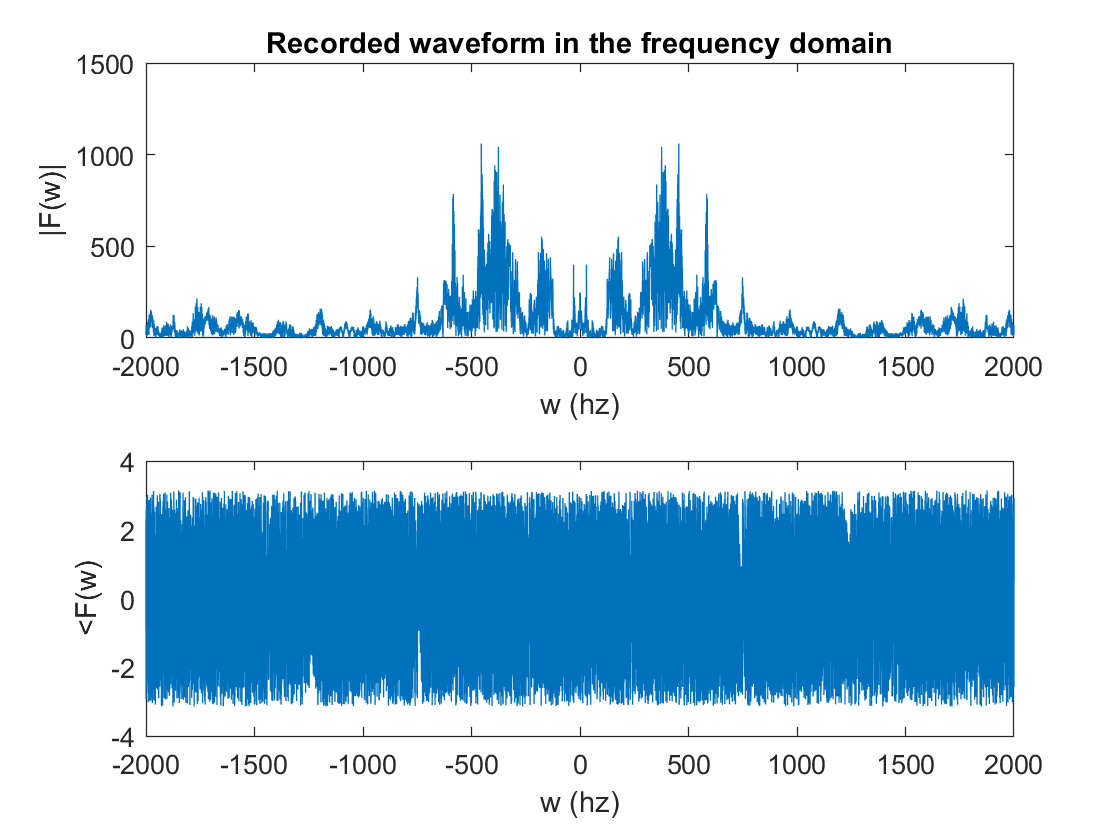

F0 = fftshift(fft(f)); %compute the Fourier transform
fValues= linspace(-FS/2,FS/2,FS*DURATION); %frequency in hz for easier intuition
MAX_FREQ = 2000;

close all;
subplot(2,1,1);
plot(fValues,abs(F0));
xlabel('w (hz)');
ylabel('|F(w)|');
xlim([-MAX_FREQ MAX_FREQ]);
title('Recorded waveform in the frequency domain');
subplot(2,1,2);
plot(fValues,angle(F0));
xlim([-MAX_FREQ MAX_FREQ]);
xlabel('w (hz)');
ylabel('<F(w)');

Now, let's manipulate the signal. Let's try speeding it up!

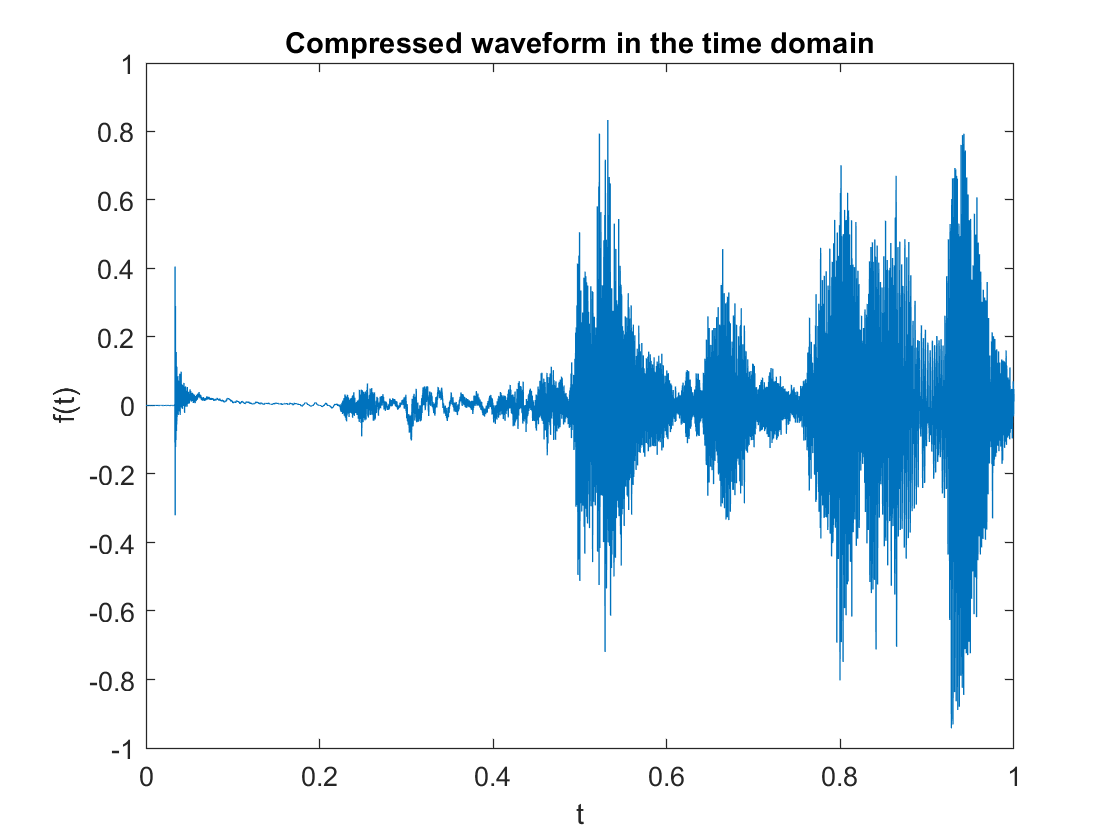

SCALE_FACTOR = 3;
fCompressed = f(1:SCALE_FACTOR:end);

close all;
plot((1:length(fCompressed))/FS,fCompressed);
title('Compressed waveform in the time domain');
xlabel('t');
ylabel('f(t)');

It's hard to see the difference, but you can hear it:

sound(fCompressed,FS);

Let's look at what this does in the frequency domain.

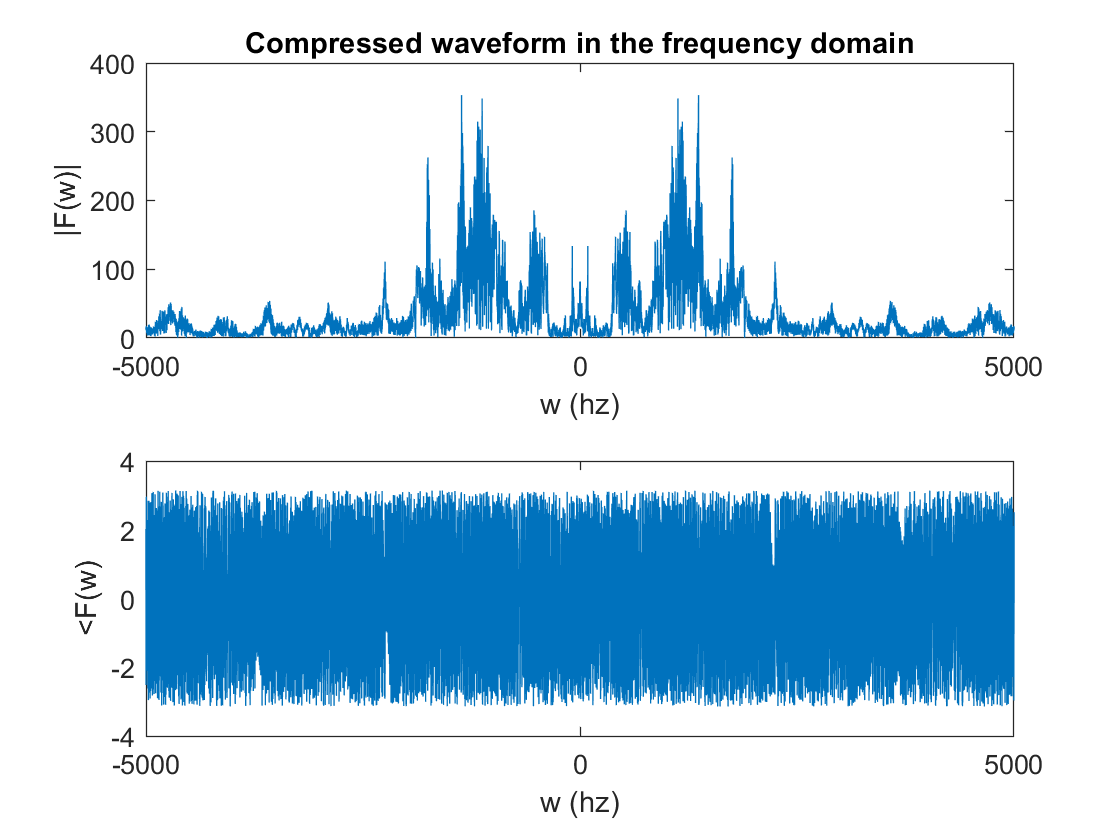

F1 = fftshift(fft(fCompressed)); %compute the Fourier transform
fValues= linspace(-FS/2,FS/2,FS*DURATION/SCALE_FACTOR); %frequency in hz for easier intuition
MAX_FREQ = 5000;

close all;
subplot(2,1,1);
plot(fValues,abs(F1));
xlabel('w (hz)');
ylabel('|F(w)|');
xlim([-MAX_FREQ MAX_FREQ]);
title('Compressed waveform in the frequency domain');
subplot(2,1,2);
plot(fValues,angle(F1));
xlim([-MAX_FREQ MAX_FREQ]);
xlabel('w (hz)');
ylabel('<F(w)');

Let's see what manipulations in the frequency domain do. In particular, let's listen to the signal with the phase set to zero.

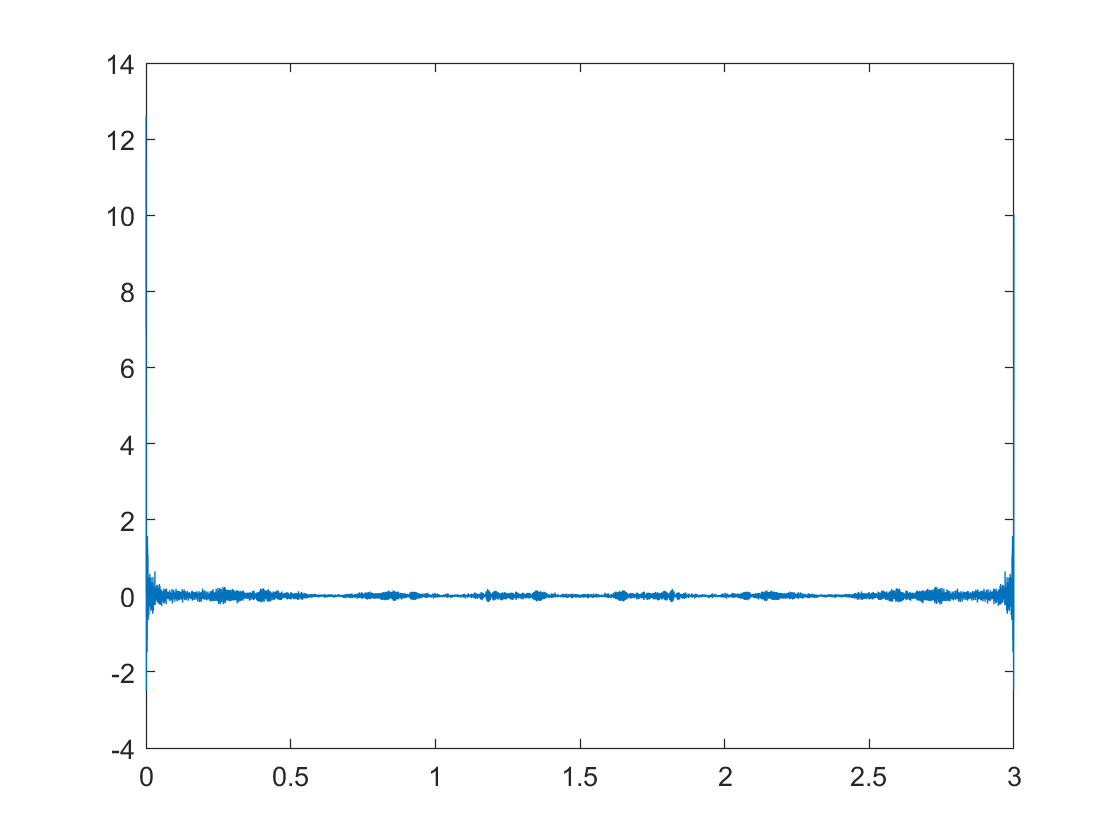

FMag = abs(F0);
fMag = ifft(ifftshift(FMag));

close all;
plot(tValues, fMag);

sound(fMag,FS);

Kinda trippy! The phase encodes the relative ordering of the frequency components: how do we line them up? When we throw out the phase, we jumble up the signal components. Let's try listening to *just* the phase.

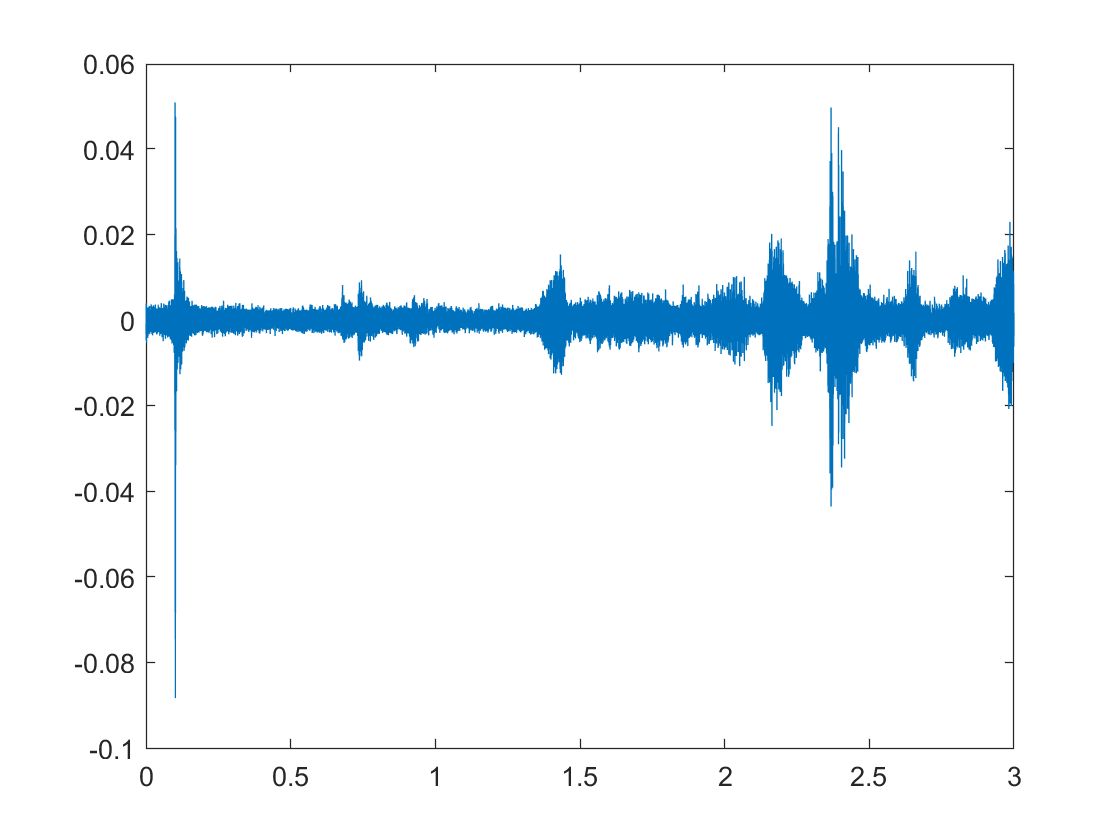

Fphase = exp(1i*angle(F0));
fPhase = ifft(ifftshift(Fphase));

close all;
plot(tValues,fPhase);

sound(fPhase,FS);

We've lost a lot of important information! But we have the ordering of the signal correct, which is why you can still make out the words.

Let's try *reversing* the phase. This is equivalent to taking the complex conjugate of the Fourier transform.

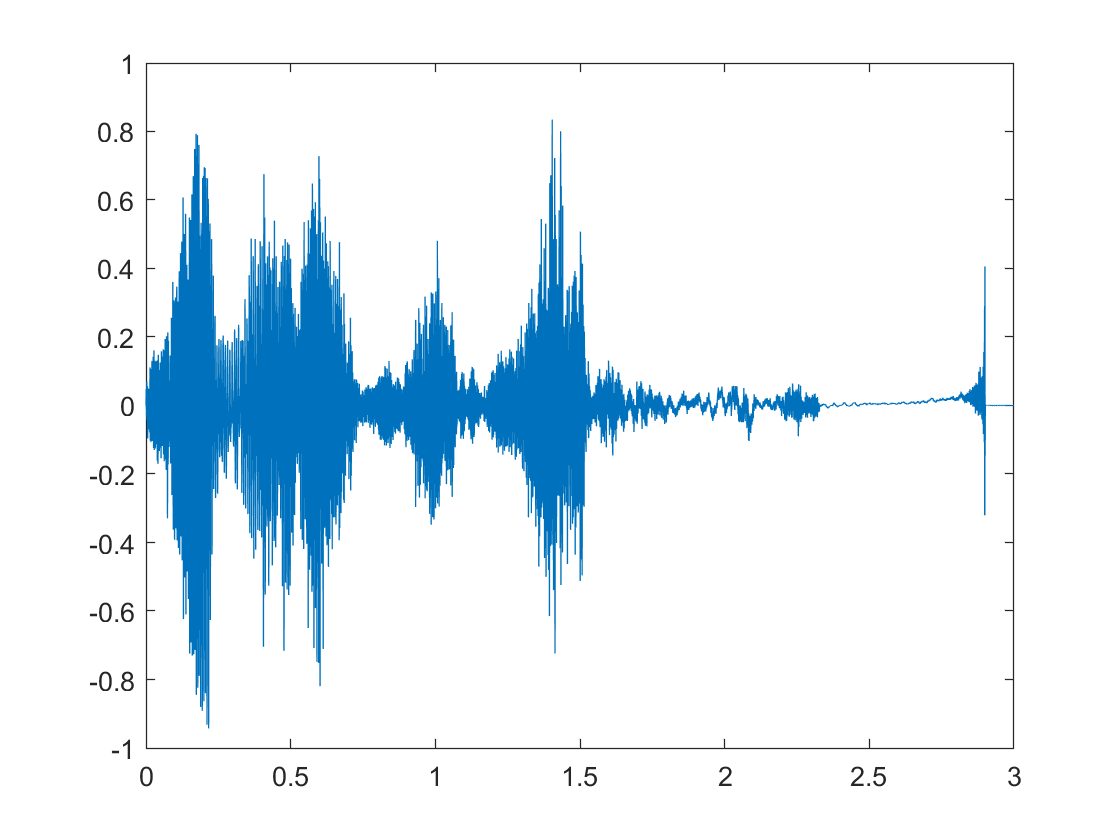

Frev = conj(F0);
fRev = ifft(ifftshift(Frev));

plot(tValues,fRev);

sound(fRev,FS);

We prove this analyitically: reversing the phase corresponds to reversing the signal in time! The upshot of these exercises is that the phase encodes important information about the ordering of frequency components in a signal. It is often difficult to get intuition out of a plot or an algebraic expression for the phase, but what happens when we *manipulate* the phase of a signal is very intiuitive.

Let's try a more explicit operation to adjust the frequency: multiplication by a cosine.

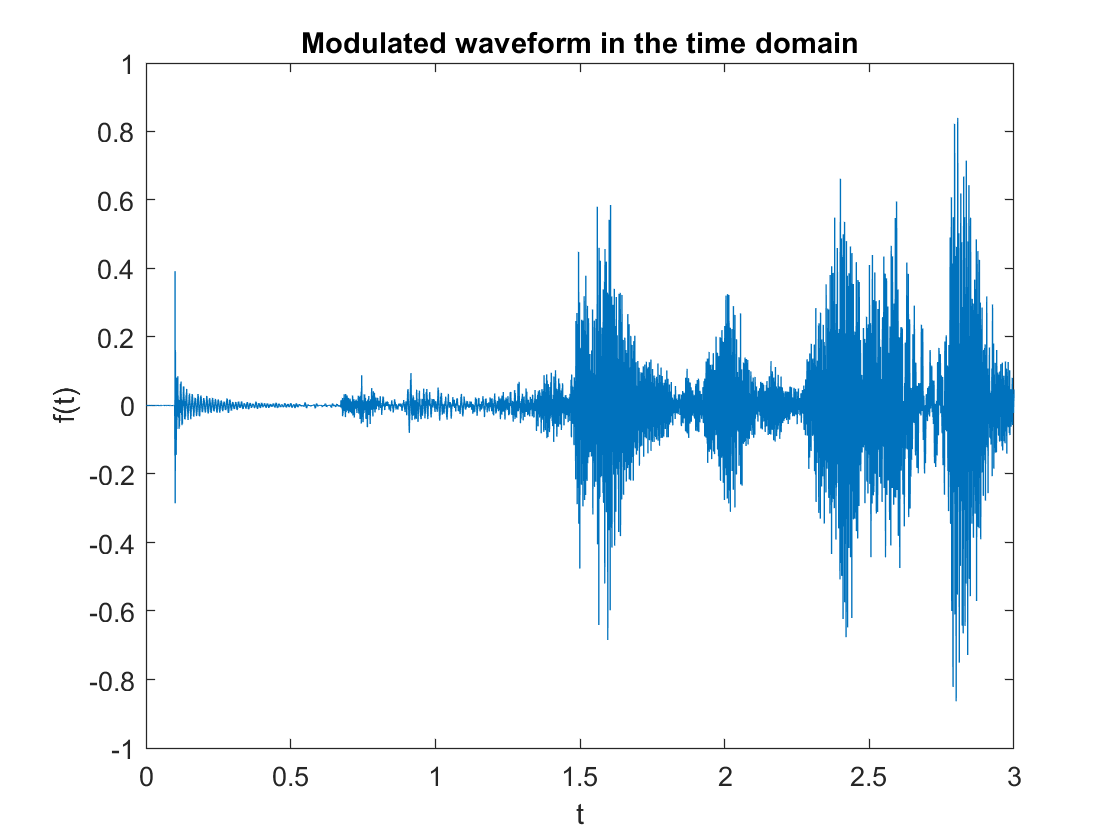

FREQ = 100; %frequency in hz
fModulated = f'.*cos(2*pi*FREQ*tValues);

close all;
plot(tValues,fModulated);
title('Modulated waveform in the time domain');
xlabel('t');
ylabel('f(t)');

The difference is again hard to see, but not to hear:

sound(fModulated,FS);

Let's see if this does what we expect to the FT of the signal.

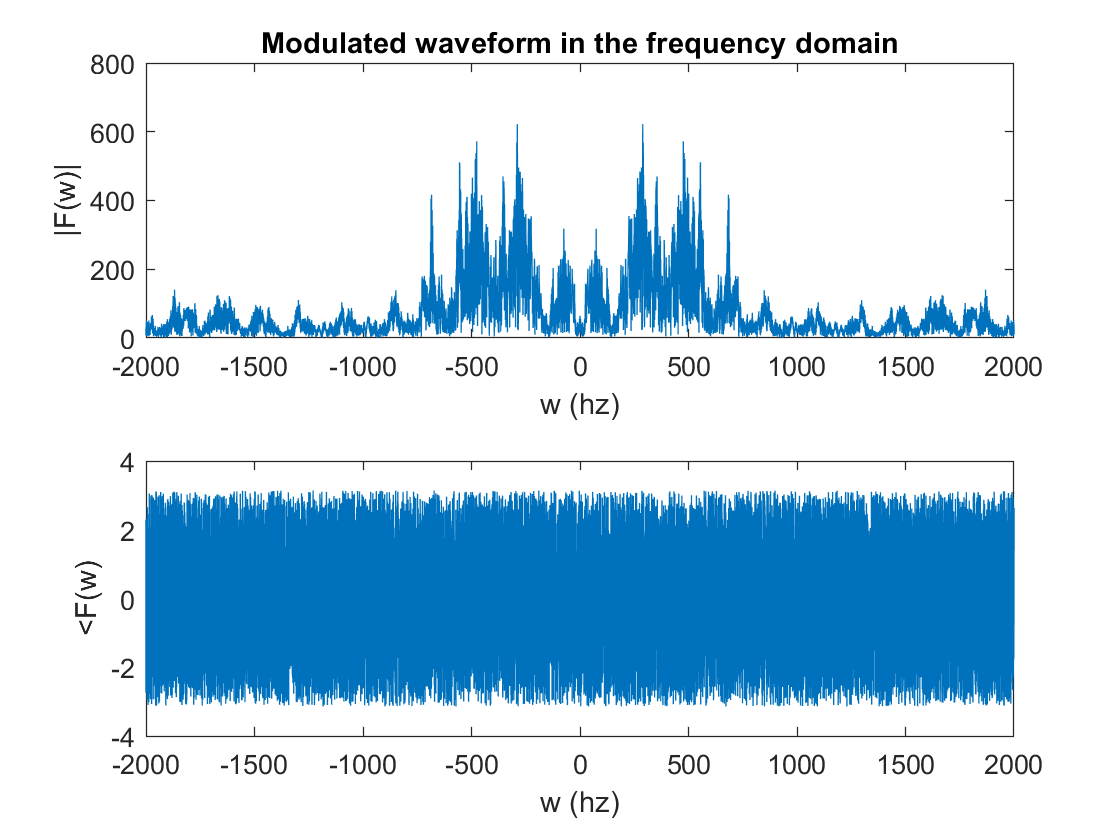

F2 = fftshift(fft(fModulated)); %compute the Fourier transform
fValues= linspace(-FS/2,FS/2,FS*DURATION); %frequency in hz for easier intuition
MAX_FREQ = 2000;

close all;
subplot(2,1,1);
plot(fValues,abs(F2));
xlabel('w (hz)');
ylabel('|F(w)|');
xlim([-MAX_FREQ MAX_FREQ]);
title('Modulated waveform in the frequency domain');
subplot(2,1,2);
plot(fValues,angle(F2));
xlim([-MAX_FREQ MAX_FREQ]);
xlabel('w (hz)');
ylabel('<F(w)');

Sure enough, we get a copy of the spectrum scaled UP by the shifting frequency, and a copy shifted down!